# This code is to redo the sharim's paper algorithm

## VR-PCA algorithm

**Parameters:** steps size \eta, epoch length m

**Input**: Data matrix X = (x_1, ..., x_n); Initial unit vector w_tidle_0

**for** s = 1,2, ... **do**

    u_tidle = 1/n * \sum_{i=1}^n x_i (x_i^T w_tidle_{s-1})

    w_0 = w_tidle_{s-1}

    **for ...**

clear all; clc;

# **Input:**

## **Create data matrix X**

% Create a fake X matrix with parabolic decay singular value
d = 200;   % dimension of data
n = 1000;    % number of instances

Eigen_gap_array = [0.16, 0.05, 0.016, 0.005];

num_loop = 60;

figure; hold on;
for i = 1:numel(Eigen_gap_array)
    Eigen_gap = Eigen_gap_array(i);
    
    [X , first_left_eigen_vec, w_tidle_0] = form_matrix(d, n, Eigen_gap);
    Error = VRPCA(X, w_tidle_0, first_left_eigen_vec, d, n, num_loop)

    plot(Error, 'LineWidth', 2 ,'DisplayName',['Eigen gap = ' num2str(Eigen_gap)])
    
end

Error =    -2.6360   -3.3009   -3.9623   -4.6183   -5.2680   -5.9101   -6.5437   -7.1680   -7.7821   -8.3858   -8.9791   -9.5624  -10.1365  -10.7023  -11.2610  -11.8136  -12.3613  -12.9061  -13.4494  -13.9908  -14.5074  -15.0515  -15.6536      -Inf  -15.6536  -15.6536  -15.3525  -15.3525      -Inf  -15.3525  -15.3525      -Inf  -15.3525  -15.3525  -15.6536  -15.3525  -15.6536  -15.3525      -Inf  -15.6536  -15.3525  -15.6536  -15.6536  -15.6536  -15.3525  -15.3525      -Inf  -15.6536      -Inf  -15.6536


Error =    -4.0640   -4.2574   -4.4500   -4.6418   -4.8329   -5.0231   -5.2125   -5.4012   -5.5891   -5.7763   -5.9627   -6.1485   -6.3335   -6.5179   -6.7017   -6.8848   -7.0673   -7.2493   -7.4307   -7.6115   -7.7919   -7.9717   -8.1511   -8.3300   -8.5085   -8.6866   -8.8643   -9.0416   -9.2186   -9.3952   -9.5716   -9.7476   -9.9233  -10.0987  -10.2739  -10.4488  -10.6235  -10.7979  -10.9721  -11.1462  -11.3200  -11.4937  -11.6671  -11.8404  -12.0135  -12.1864  -12.3593  -12.5320  -12.7037  -12.8761


Error =    -3.5595   -3.6256   -3.6915   -3.7573   -3.8230   -3.8886   -3.9541   -4.0194   -4.0846   -4.1497   -4.2146   -4.2794   -4.3440   -4.4085   -4.4728   -4.5370   -4.6010   -4.6649   -4.7286   -4.7921   -4.8555   -4.9187   -4.9818   -5.0447   -5.1075   -5.1701   -5.2325   -5.2948   -5.3569   -5.4189   -5.4807   -5.5423   -5.6039   -5.6652   -5.7264   -5.7875   -5.8484   -5.9092   -5.9698   -6.0303   -6.0907   -6.1509   -6.2110   -6.2710   -6.3308   -6.3905   -6.4501   -6.5096   -6.5689   -6.6281


Error =    -3.7827   -3.8030   -3.8232   -3.8434   -3.8637   -3.8839   -3.9042   -3.9244   -3.9447   -3.9650   -3.9853   -4.0055   -4.0258   -4.0461   -4.0664   -4.0867   -4.1070   -4.1273   -4.1476   -4.1679   -4.1882   -4.2085   -4.2288   -4.2491   -4.2695   -4.2898   -4.3101   -4.3304   -4.3507   -4.3710   -4.3913   -4.4116   -4.4319   -4.4522   -4.4725   -4.4928   -4.5132   -4.5335   -4.5538   -4.5741   -4.5944   -4.6146   -4.6349   -4.6552   -4.6755   -4.6958   -4.7161   -4.7364   -4.7567   -4.7769


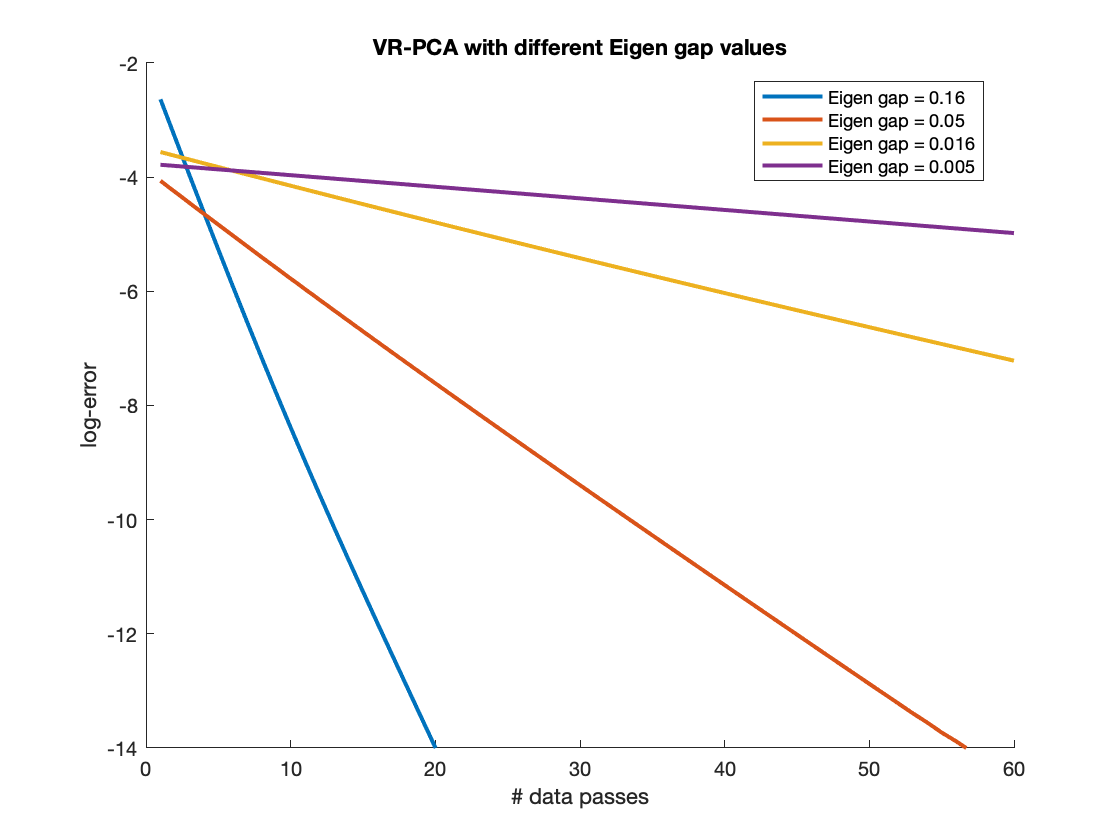


ylabel('log-error')
xlim([0 num_loop])
xlabel('# data passes')
ylim([-14 -2])
legend('Location',"best")
title('VR-PCA with different Eigen gap values')

# Extra functions:

## Create data X, w_tidle_0, first_left_eigen_vec

function [X, first_left_eigen_vec, w_tidle_0] = form_matrix(d, n, Eigen_gap)

% Eigen values matrix
D = diag([1,1-linspace(1,1.4,5)*Eigen_gap,abs(randn(1,d-6)/d)]);
U = orth(rand(d,d)); V = orth(rand(n,d));

% Building matrix
X = U * D * V';

first_left_eigen_vec = U(:,1);
noise = rand(d,1) * 1 * max(V(1,:));
w_tidle_0 = first_left_eigen_vec + noise;
w_tidle_0 = w_tidle_0 / norm(w_tidle_0);

end

## Implementation of algorithm function

function Error = VRPCA(X, w_tidle_0, first_left_eigen_vec, d, n, num_loop)
% calculating Step size \eta parameter
r_bar = 1/n * norm(X,'fro')^2; %
eta = 1/(r_bar * sqrt(n));

% picking epoch length m = n
m = n/2;

A = 1/n * X * X';

for s = 1:num_loop
    
    if s == 1
        w_tidle_s_1 = w_tidle_0;
    else
        w_tidle_s_1 = w_tidle_s;
    end
    
    u_tidle = A * w_tidle_s_1;
    w_0 = w_tidle_s_1;
    
    for t = 1:m
        
        if t == 1
            w_t_1 = w_0;
        else
            w_t_1 = w_t;
        end
        
        i_t = randperm(n);
        
%         w_t_prime = (eye(d) + eta * A) * w_t_1 + ...
%             eta * (X(:,i_t) * X(:,i_t)' - A) * (w_t_1 - w_tidle_s_1);
        w_t_prime = w_t_1 + eta * (X(:,i_t) * (X(:,i_t)' * w_t_1 - X(:,i_t)' * w_tidle_s_1) + u_tidle);
        
        w_t = 1/norm(w_t_prime) * w_t_prime;
        
    end
    
    w_tidle_s = w_t;
    
    Error(s) = real(log10(1-norm(X' * w_tidle_s)^2/norm(X'*first_left_eigen_vec)^2));
    
end

end
